## **Przetwarzanie Sygnałów Cyfrowych**

# **Parametry sygnalow cyfrowych**

## Jan Rosa 410269 AiR

### Wstęp

### 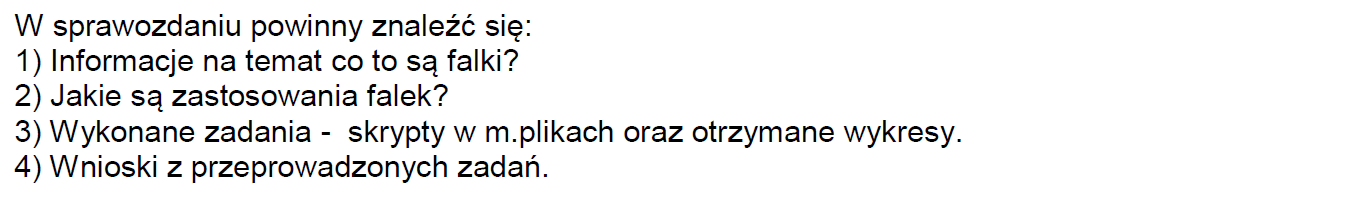

### Zad 1

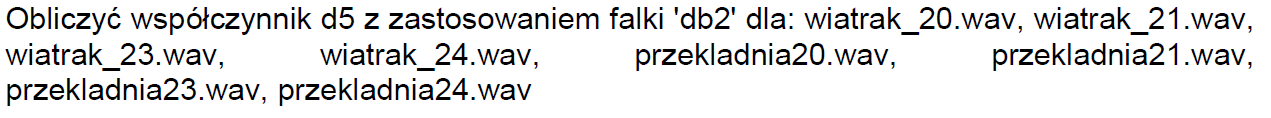

clear all;
files_names = ["wiatrak_20.wav"; "wiatrak_21.wav"; 'wiatrak_23.wav'; 'wiatrak_24.wav'; 'przekladnia20.wav'; 'przekladnia21.wav'; 'przekladnia23.wav'; 'przekladnia24.wav'];
files = [[]];
for i = 1:size(files_names)
    [data, fz] = audioread(files_names(i));
    files(i,:) = data;
end
t = (0:size(data)-1)/fz;
clear data;
clear i;

Kolejne wiersz oznaczają współczynniki kolejnych ww. plików

d5_vec = [];
for i = 1:size(files)
data = files(i,:);
[c,l] = wavedec(data,5,'db2');
[d5] = detcoef(c,l,5);
d5_vec(i,:) = d5; 
end
clear d5;
d5_vec

d5_vec =     0.0002   -0.5798    0.2724   -0.1505   -0.5589   -0.0098   -0.5030   -0.1771   -0.4265    0.3302   -0.0300    1.2519   -0.0142   -0.6832    0.0973    1.2089    0.3694   -0.5200   -0.1444   -0.7393    0.6785   -0.0553   -0.3969   -0.6022    0.7451    0.2616   -0.1941   -0.8033    0.2824    0.4698   -0.2160   -0.6446   -0.8639    0.2733    0.0934   -0.2435   -0.2792    0.0809    0.1346   -0.3328   -0.4599    0.0523    1.5312    0.2685   -0.7714    0.0986    0.7358   -0.2782    0.6960   -0.1146
   -0.0237    1.0299   -0.5605    0.6642   -0.3540   -0.1975    0.6721   -0.2895    0.3033    0.0564   -0.2186    0.1719   -0.5497   -0.1405   -0.2101    0.3554    1.3722   -0.5476   -0.3520    0.3182   -0.0124    0.1578    0.7817   -0.1783   -0.2178    0.3473    0.5126   -0.6309   -0.3876   -0.4487    0.4804    0.5609   -0.1807   -0.4207   -0.9315    0.8682    0.1122   -0.0190   -0.2978    0.4940   -0.0143    0.5282   -0.5376   -0.6229    0.1964    0.6739   -0.1586   -0.2144    0.1024

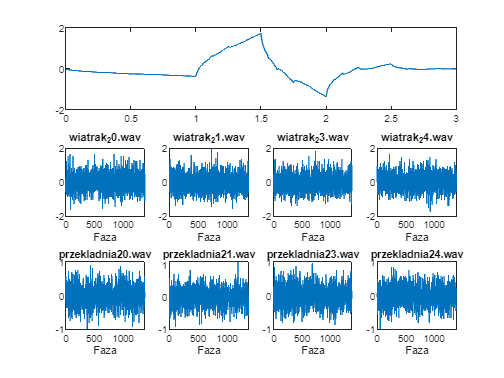

plotwavelet(d5_vec, 'db2', files_names)

### Zad 2

Obliczyć współczynnik a4 z zastosowaniem falki 'coif2' dla: wiatrak_20.wav,

wiatrak_21.wav, wiatrak_23.wav, wiatrak_24.wav, przekladnia20.wav, przekladnia21.wav,

przekladnia23.wav, przekladnia24.wav

a4_vec = [];
for i = 1:size(files)
data = files(i,:);
[c,l] = wavedec(data,4,'coif2');
[a4] = appcoef(c,l,'coif2',4);
a4_vec(i,:) = a4; 
end
clear a4;
a4_vec

a4_vec =     0.8847    0.8637    0.8575    0.8751    0.8698    0.9195    0.4358   -0.0378    0.3981   -0.2795   -0.4244    0.4215   -0.4578   -0.0960    0.4405    0.5760   -0.1044   -0.0013   -0.2466   -0.0710   -0.7703    0.4494    0.2016    0.3397   -0.4817   -0.2372    0.4860   -0.6788   -0.0240    0.4619    0.3907   -0.4261    0.6594   -1.0185    0.6253   -0.5824    0.0136    0.4772    0.2997   -0.1900    0.4291   -0.4315   -0.5131   -0.5730    0.8968   -0.0462   -0.0787    0.5664   -0.2408   -0.0680
   -0.0921   -0.1273   -0.0813   -0.0960   -0.1245   -0.1977    0.4450    0.2226   -0.8337    0.2551    0.2189    0.4593   -0.4454    0.3339    0.3673   -1.0316    0.0739    0.4089   -0.1771    0.1371    0.6789   -0.2730    0.0503   -0.4096   -0.0313   -0.0797    0.4935   -0.0367   -0.4061    0.1095   -0.1853   -0.3740    0.0773    0.2706    0.4385   -0.0301   -0.2285    0.9074   -1.5688    0.6031   -0.0728   -0.4810    0.6052   -0.0496    0.1306   -0.0284    0.1110   -0.2223    0.3185

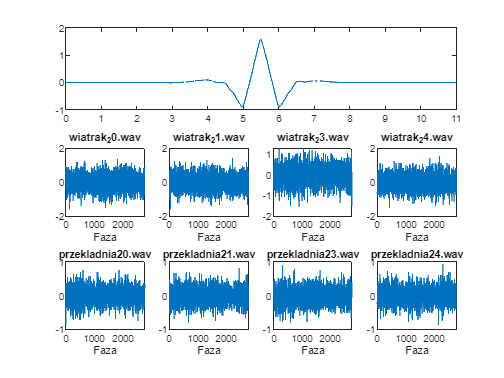

plotwavelet(a4_vec, 'coif2',files_names)

### Zad 3

Obliczyć współczynnik a8 z zastosowaniem falki 'coif2' dla: wiatrak_20.wav,

wiatrak_21.wav, wiatrak_23.wav, wiatrak_24.wav, przekladnia20.wav, przekladnia21.wav,

przekladnia23.wav, przekladnia24.wav

a8_vec = [];
for i = 1:size(files)
data = files(i,:);
[c,l] = wavedec(data,8,'coif2');
[a8] = appcoef(c,l,'coif2',8);
a8_vec(i, :) = a8; 
end
clear a8;
a8_vec

a8_vec =     3.3152    3.3928    3.4003    3.4003    3.3609    3.6367    1.7409   -0.2435    0.0540   -0.0330    0.0688    0.0403   -0.0377    0.0730   -0.0013    0.0122    0.0587    0.0234    0.0744   -0.1284    0.0076   -0.0813   -0.1198    0.0434   -0.0908   -0.0528   -0.0038    0.0284   -0.0283    0.0132    0.0068    0.0109    0.0463    0.0172   -0.0837   -0.0141   -0.0492    0.0797   -0.0692    0.0274    0.0741    0.0790   -0.0383   -0.0182    0.0469    0.0416    0.0765    0.0248    0.0578    0.0097
   -0.3001   -0.2621   -0.2962   -0.3553   -0.2630   -0.3238   -0.0770    0.0335   -0.0121   -0.0464   -0.0457    0.0532    0.0613   -0.0712   -0.0270    0.0736   -0.0353   -0.0494   -0.0040   -0.0216    0.1511   -0.0062   -0.0593   -0.0672   -0.0034   -0.0534   -0.0141   -0.0450    0.0280    0.0608    0.0146    0.0155    0.0606   -0.0537    0.0446   -0.1122   -0.0651   -0.0455   -0.0843   -0.0148    0.0031    0.0795   -0.0321    0.0272   -0.0416    0.0065   -0.0228   -0.0822   -0.0265

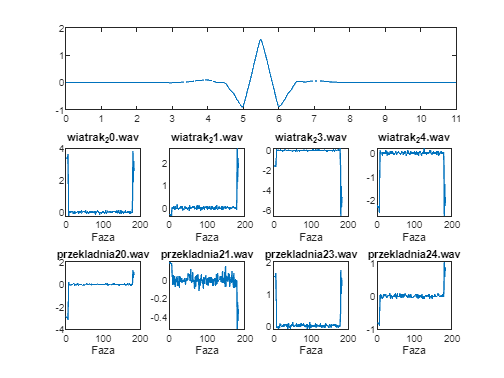

plotwavelet(a8_vec, 'coif2',files_names)

### Zad 4

Obliczyć współczynnik d10 z zastosowaniem falki 'haar' dla: wiatrak_20.wav,

wiatrak_21.wav, wiatrak_23.wav, wiatrak_24.wav, przekladnia20.wav, przekladnia21.wav,

przekladnia23.wav, przekladnia24.wav

d10_vec = [];
for i = 1:size(files)
data = files(i,:);
[c,l] = wavedec(data,10,'haar');
[d10] = detcoef(c,l,10);
d10_vec(i,:) = d10; 
end
clear d10;
d10_vec

d10_vec =     0.0589    0.0642    0.0135   -0.0423    0.0408    0.0501    0.1349    0.0373   -0.0108   -0.1394   -0.0188    0.0210   -0.0723   -0.0843    0.1935   -0.0743   -0.0867   -0.0048   -0.0268    0.0628    0.0051   -0.1425   -0.2628    0.0472   -0.0293    0.0607    0.0556    0.0802    0.0009   -0.0099    0.0043   -0.0092   -0.1119   -0.0706    0.0696   -0.0475    0.0037   -0.1451   -0.0461   -0.0349   -0.0615   -0.0162   -0.0210   -0.0000
    0.2303    0.1182    0.0986   -0.0717    0.0720   -0.0513    0.0760    0.0477   -0.0103    0.1165    0.1421    0.0915    0.0062   -0.1226    0.1612   -0.0180   -0.0335    0.0163    0.0838    0.0352   -0.0562   -0.0320   -0.2350   -0.0274    0.0988   -0.0291   -0.1061   -0.1349   -0.0959   -0.0775   -0.1287   -0.0080    0.0009   -0.0928   -0.2619    0.0744    0.0162   -0.0021   -0.1496   -0.0187   -0.0374   -0.0345    0.0119   -0.0000
    0.0118   -0.0256   -0.0343    0.0276   -0.0456   -0.0686    0.1115    0.1074   -0.0450   -0.0505   -0.07

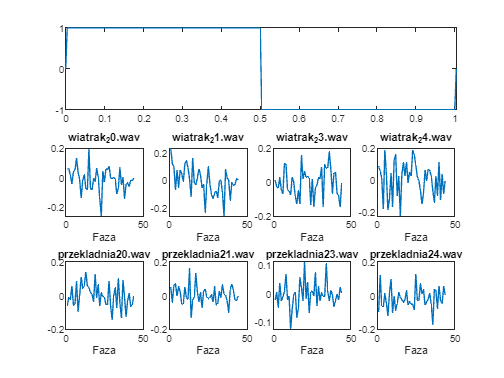

plotwavelet(d10_vec, 'haar',files_names)

### Zad 5

Obliczyć współczynnik d10 z zastosowaniem falki 'dmey' dla: wiatrak_20.wav,

wiatrak_21.wav, wiatrak_23.wav, wiatrak_24.wav, przekladnia20.wav, przekladnia21.wav,

przekladnia23.wav, przekladnia24.wav

d10_vec = [];
for i = 1:size(files)
data = files(i,:);
[c,l] = wavedec(data,10,'dmey');
[d10] = detcoef(c,l,10);
d10_vec(i,:) = d10; 
end
clear d10;
d10_vec

d10_vec =     0.1945   -0.0623    0.0803   -0.0723    0.0499    0.0214   -0.0959    0.0555   -0.0143   -0.0238    0.0616   -0.0727   -0.0000    0.0491   -0.0541    0.0320    0.0088   -0.0579    0.1141   -0.0208   -0.0204    0.0421   -0.0626    0.0091    0.0515   -0.0842    0.0679    0.0032   -0.0347    0.0627   -0.0784   -0.0357    0.0596   -0.0532    0.0233    0.0211   -0.0697    0.0813   -0.0095   -0.0346    0.0475   -0.0439    0.0165    0.0755   -0.0780    0.0205    0.0332   -0.0874    0.0763   -0.3530
   -0.0757   -0.0060   -0.1092    0.0754   -0.0420   -0.0134    0.0932   -0.0443    0.0639    0.0867   -0.0448    0.0989    0.0184   -0.0439    0.0872   -0.0664   -0.0335    0.0371   -0.1105    0.0002   -0.0095   -0.1144    0.0546   -0.0242   -0.0446    0.0814   -0.0549    0.0341    0.0977   -0.0433    0.0848    0.0455   -0.0430    0.0981   -0.0322   -0.0404    0.0589   -0.1021   -0.0163    0.0077   -0.1266    0.0282   -0.0270   -0.0720    0.0700   -0.0373   -0.0063    0.1203   -0.047

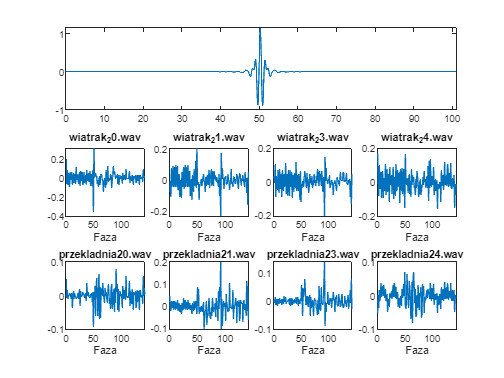

plotwavelet(d10_vec, 'dmey',files_names)

### Zad 6

Obliczyć współczynnik a8 z zastosowaniem falki 'bior3.5' dla: wiatrak_20.wav,

wiatrak_21.wav, wiatrak_23.wav, wiatrak_24.wav, przekladnia20.wav, przekladnia21.wav,

przekladnia23.wav, przekladnia24.wav

a8_vec = [];
for i = 1:size(files)
data = files(i,:);
[c,l] = wavedec(data,8,'bior3.5');
[a8] = appcoef(c,l,'bior3.5',8);
a8_vec(i,:) = a8; 
end
clear a8;
a8_vec

a8_vec =     6.3051    4.1024    6.4956    4.1024    6.3051   -1.6471    0.6470   -0.2338    0.0849    0.1427   -0.1631    0.1006    0.0524   -0.0210    0.0386    0.0757   -0.1079    0.2918   -0.3303   -0.0128   -0.0016   -0.0378   -0.1924    0.1605   -0.2144    0.0796    0.0963   -0.2370    0.2652   -0.1853    0.1842   -0.0838   -0.0381    0.1009   -0.2262    0.1736   -0.1552    0.1309   -0.0095   -0.0126    0.2080   -0.1171   -0.0688    0.1317    0.0358    0.1043    0.0028   -0.0692    0.1990   -0.0445
   -3.8105   -2.1448   -3.9757   -2.1448   -3.8105    1.2401   -0.3776   -0.1238    0.1659   -0.2524    0.4297   -0.4083    0.2322   -0.1159    0.0514    0.0892   -0.3207    0.2034    0.0930   -0.0503   -0.0077    0.0790   -0.2430    0.0855   -0.1323    0.2098   -0.3072    0.1485    0.2103   -0.2465    0.1868   -0.0143    0.0383   -0.1047   -0.1289    0.0638   -0.1016   -0.2170    0.2343   -0.0346   -0.0435    0.0434   -0.0395    0.1413   -0.2302   -0.0056    0.1440   -0.2976    0.1970

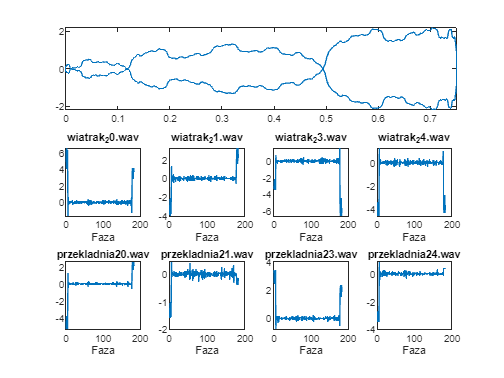

plotwavelet(a8_vec, 'bior3.5',files_names)

### Zad 7

Wykonać dekompozycję obrazu 'wiatrak_20.wav' funkcją wavedec(), waverec(). Do tego celu

zastosować falkę 'coif2'. Następnie zrekonstruować obraz falką 'coif2'. Proszę zaobserwować

różnice. Proszę użyć 12 stopnia dekompozycji.

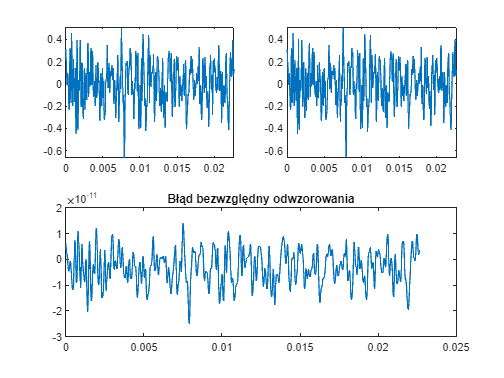

data = files(1,:);
[c,l] = wavedec(data,12,'coif2');
x = waverec(c, l, 'coif2');
probe = 1000;
figure
subplot(2,2,1)
plot(t(1:probe), data(1:probe));
subplot(2,2,2)
plot(t(1:probe), x(1:probe))
subplot(2,2,[3 4])
plot(t(1:probe), data(1:probe)-x(1:probe))
title("Błąd bezwzględny odwzorowania")

Rekonstrukcja z postaci falkowej 12 stopnia dobrze odwzorowuje orgunalny sygnał.

### Zad 8

Wykonać dekompozycję obrazu 'wiatrak_20.wav' funkcjami wavedec(), waverec(). Do tego

celu zastosować falkę 'coif2'. Następnie zrekonstruować obraz falką 'haar'. Proszę zaobserwować

różnice. Proszę użyć 12 stopnia dekompozycji.

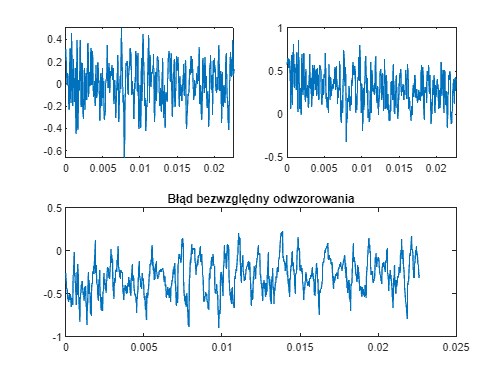

data = files(1,:);
[c,l] = wavedec(data,12,'coif2');
x = waverec(c, l, 'haar');
probe = 1000;
figure
subplot(2,2,1)
plot(t(1:probe), data(1:probe));
subplot(2,2,2)
plot(t(1:probe), x(1:probe))
subplot(2,2,[3 4])
plot(t(1:probe), data(1:probe)-x(1:probe))
title("Błąd bezwzględny odwzorowania")

Wyniki są bez sensu, aby poprawnie zrekonstruować sygnał należy użyć tej samej falki jak przy transformacie falkowej

### Zad 9

Obliczyć współczynnik a12 z zastosowaniem falki 'sym2' dla: wiatrak_20.wav,

wiatrak_21.wav, wiatrak_23.wav, wiatrak_24.wav, przekladnia20.wav, przekladnia21.wav,

przekladnia23.wav, przekladnia24.wav

a12_vec = [];
for i = 1:size(files)
data = files(i,:);
[c,l] = wavedec(data,12,'sym2');
[a12] = appcoef(c,l,'sym2',12);
a12_vec(i,:) = a12; 
end
clear a12;
a12_vec

a12_vec =    16.0570   14.3817   -0.0363   -0.0100    0.0730   -0.0285    0.0017   -0.1080    0.0457    0.0578   -0.0108   -0.7163    4.6972
   -5.6362   -5.0331   -0.0013   -0.0736   -0.0195    0.0363   -0.0106    0.0345   -0.0386   -0.0136    0.0043   -0.4709    3.2494
  -13.9476  -12.4710   -0.0288    0.0213   -0.0263   -0.0672   -0.0212   -0.0625    0.0862    0.0566   -0.0240    1.4424   -9.9161
  -10.0384   -8.9813    0.0130   -0.0280   -0.0268   -0.0141   -0.0797   -0.0119   -0.0064    0.0265    0.0345    0.3008   -2.2251
   -6.0615   -5.4489   -0.0280   -0.0563   -0.0351   -0.0220    0.0180   -0.0464   -0.0022    0.0116   -0.0384    0.1030   -0.7195
  -10.4008   -9.2888   -0.0588   -0.0549    0.0850   -0.0106   -0.0371   -0.0272   -0.0633   -0.0020    0.0230    0.0842   -0.5372
   10.5749    9.4315   -0.0491    0.0030    0.0188    0.0083    0.0023   -0.0364   -0.0107   -0.0195   -0.0238   -0.3048    2.2145
   -2.9775   -2.6853    0.0101    0.0134    0.0200    0.0414    0.0212   

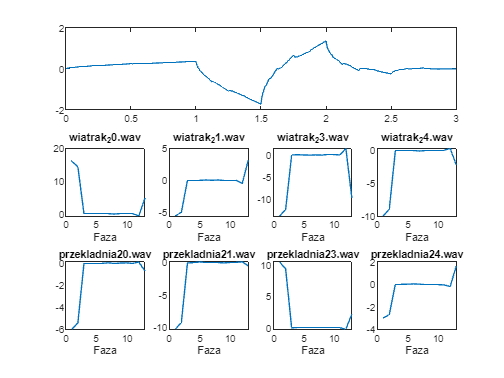

plotwavelet(a12_vec, "sym2",files_names)

### Zad 10

Obliczyć współczynnik d12 z zastosowaniem falki 'sym2' dla: wiatrak_20.wav,

wiatrak_21.wav, wiatrak_23.wav, wiatrak_24.wav, przekladnia20.wav, przekladnia21.wav,

przekladnia23.wav, przekladnia24.wav

d12_vec = [];
for i = 1:size(files)
data = files(i,:);
[c,l] = wavedec(data,12,'dmey');
[d12] = detcoef(c,l,12);
d12_vec(i,:) = d12; 
end
clear d12;
d12_vec

d12_vec =     0.4319   -0.1050    0.1049   -0.0681    0.0380    0.0099   -0.0498    0.0342   -0.0062   -0.0226    0.0435   -0.0864   -0.0103    0.0430   -0.0389    0.0229    0.0041   -0.0356    0.0589   -0.0162   -0.0143    0.0258   -0.0556    0.0093    0.0658   -0.1046    0.0738   -0.0014   -0.0146    0.0365   -0.0378   -0.0159    0.0352   -0.0315    0.0118    0.0175   -0.0614    0.0946    0.0049   -0.0193    0.0314   -0.0283    0.0078    0.0345   -0.0332   -0.0054    0.0466   -0.1077    0.0493   -0.6121
   -0.1844    0.0373   -0.0280    0.0071   -0.0045    0.0033    0.0013    0.0057    0.0003    0.0039    0.0036    0.0254    0.0090   -0.0039   -0.0025    0.0015   -0.0003   -0.0044   -0.0046   -0.0046   -0.0036    0.0038    0.0037    0.0092   -0.0070    0.0067   -0.0141    0.0010   -0.0035    0.0066    0.0039    0.0042    0.0044   -0.0043    0.0041   -0.0009    0.0060   -0.0272   -0.0100   -0.0063    0.0016   -0.0055   -0.0036    0.0012   -0.0083    0.0145   -0.0144    0.0312   -0.005

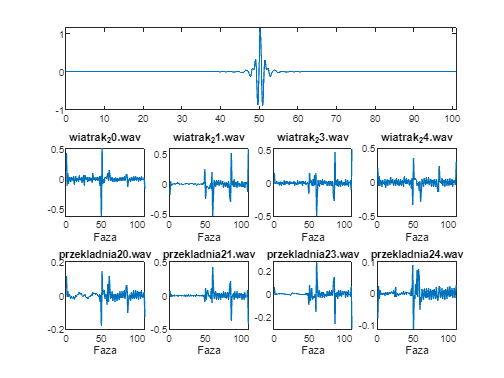

plotwavelet(d12_vec, 'dmey',files_names)

### Wnioski

1) W jaki sposób zastosować falki do ekstrakcji cech?

2) Jakie parametry falek możemy zmieniać w toolboxie?

3) Czym różnią się współczynniki a1, d1, d2, d3, d4, d5?

4) Czym różni się transformacja falkowa od filtrów?

1) Na podstawie przykładu ekstracja cech przez transfromatę falkową polega na konwolucji okresowego sygnału falki przez sygnał wejściowy, pozwala to na wykrycie cech które zawiera falka.

2)?W toolboxie możemy zmieniać rodzaj falki i stopień dekompozycji

3)a - parametr aproksymacji, d-parametr detalów, [cyfra]-stopień transformaty

4) Transformata falkowa zapobiega przeciekowi widma i przesunięć faz oraz pozwala odfiltrować sygnał nawet jeśli szumy mają tą samą częstotliwość co sygnał

function [] = plotwavelet(matrix, wavelet, files_names)    
p = matrix;
figure
[~,psi,xval] = wavefun(wavelet,0);
subplot(3,4,[1,2,3,4])
plot(xval,psi)
xlim([min(xval),max(xval)])
for q = 1:size(p)
    subplot(3,4,q+4)
    plot(p(q,:))
    title(files_names(q))
    xlabel('Faza')
end
end